%% Model definition
m= 1000; %kg, mass of the vehicle
I=1500; %kgm^2, moment of inertia of the vehicle
a=1.5; %m, distance from the center of mass to the front axle
b=1.5; %m, distance from the center of mass to the rear axle
c=1; % The distance from the center of mass to the left/right side of the tires (y axis)
parameters=[m;I;a;b;c];
%% 
V=5;
eps_0=[0;
    0.0;
    V];
u0=[0.0;0];
Ts=1e-2;
% Define model, cost function, and bounds.
sys=simp_discreteSS(eps_0,u0,parameters,Ts);
A = sys.A;
B = sys.B;

% computes a control invariant set for LTI system x^+ = A*x+B*u

system = LTISystem('A', A, 'B', B);
xlb = [-10; -10;-100];
xub = [10;10;100];
ulb = [-100; -100];
uub=-ulb;
system.x.min = xlb;
system.x.max = xub;
system.u.min = ulb;
system.u.max = uub;
Q=diag([30,1,1]);
R=eye(2)*0.1;
system.x.penalty = QuadFunction(Q);
system.u.penalty = QuadFunction(R);
%TODO: kijken welke van de 2 we nodig hebben
% InvSet = system.invariantSet() 
InvSet = system.LQRSet()

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Polyhedron in R^3 with representations:
    H-rep (irredundant) : Inequalities  20 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


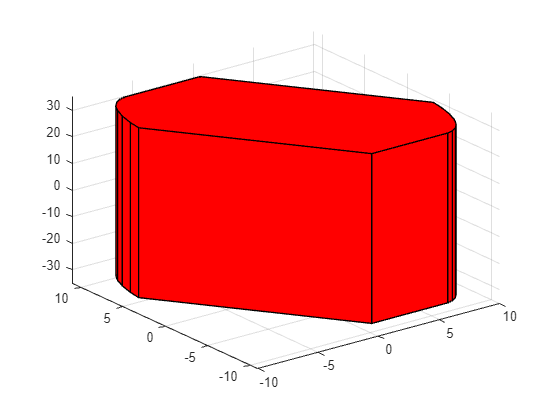

InvSet.plot()

%NEXT: Create LQR controller
%Calculate LQR gains and create system
[K,P]=dlqr(A,B,Q,R)

K =    15.8469   10.1712   -0.0000
    0.0000   -0.0000    3.1374


P =   385.1026  103.9591   -0.0000
  103.9591   64.6259   -0.0000
   -0.0000   -0.0000   63.7475


lqrsys=LTISystem('A',A-B*K,'B',B)

LTISystem with 3 states, 2 inputs, 0 outputs


Vert=InvSet.V; %Edges of set
for i=1:size(Vert,1) %Loop over all vertices
    x0=Vert(i,:);
    lqrsys.initialize(x0);
    newx=lqrsys.update(zeros(2,1)); %Zero because control is the feedback law implemented
    if InvSet.A*newx<=InvSet.b %Constraint equality
        % disp(['No problem at with step from x0 to x1:'])
        [x0
        newx']
    end
    % disp([x0;newx'])
end

ans =     0.1080  -10.0000  -31.8738
   -0.3503   -8.3333  -31.3738


ans =    -9.1393    4.4075  -31.8738
   -8.8772    6.0742  -31.3738


ans =    -8.9805    5.6100  -31.8738
   -8.6645    7.0309  -31.3738


ans =    -8.2855    8.1275  -31.8738
   -7.8589    8.9380  -31.3738


ans =    -7.3980    9.4985  -31.8738
   -6.9144    9.8422  -31.3738


ans =    -6.4184   10.0000  -31.8738
   -5.9184   10.0000  -31.3738


ans =    -6.9144    9.8422  -31.8738
   -6.4184   10.0000  -31.3738


ans =    -7.8589    8.9380  -31.8738
   -7.3980    9.4985  -31.3738


ans =    -8.6645    7.0309  -31.8738
   -8.2855    8.1275  -31.3738


ans =    -0.1080   10.0000  -31.8738
    0.3503    8.3333  -31.3738


ans =     9.1393   -4.4075  -31.8738
    8.8772   -6.0742  -31.3738


ans =     8.9805   -5.6100   31.8738
    8.6645   -7.0309   31.3738


ans =     8.6645   -7.0309   31.8738
    8.2855   -8.1275   31.3738


ans =     8.2855   -8.1275   31.8738
    7.8589   -8.9380   31.3738


ans =     7.8589   -8.9380   31.8738
    7.3980   -9.4985   31.3738


ans =     7.3980   -9.4985   31.8738
    6.9144   -9.8422   31.3738


ans =     6.9144   -9.8422   31.8738
    6.4184  -10.0000   31.3738


ans =     6.4184  -10.0000   31.8738
    5.9184  -10.0000   31.3738


ans =    -0.1080   10.0000   31.8738
    0.3503    8.3333   31.3738


ans =     9.1393   -4.4075   31.8738
    8.8772   -6.0742   31.3738


ans =    -9.1393    4.4075   31.8738
   -8.8772    6.0742   31.3738


ans =     0.1080  -10.0000   31.8738
   -0.3503   -8.3333   31.3738


%Check for all sets in inv_set.V if Ax<=b holds after state update